%闪烁版本的不间断干扰
% === 参数设置 ===
close all; clear; clc
j = sqrt(-1);

fs = 100e6;           % 采样频率
ts = 1/fs;
B = 10e6;            % 带宽
fc = 40e6;           % 中心频率
label = 17;         %FJ_DFTJ

% === LFM脉冲 ===
taup = 10e-6;        % LFM脉宽
Ntau = round(taup * fs);
ttau = (-Ntau/2 : Ntau/2-1) * ts;
lfm = exp(1j*pi*B/taup * ttau.^2);  % 基带LFM脉冲

% === 多脉冲参数 ===
Np = 16;                    % 脉冲个数
PRI = 4e-3;                 % 脉冲重复间隔 4ms
PRI = 200e-6;                 % 脉冲重复间隔 200 μs
PRI_samp = round(PRI * fs);   % 每个PRI的采样点
N_total = Np * PRI_samp;      % 总采样点数
t_total = (0:N_total-1) * ts; % 时间轴

% === 构造发射信号 ===
tx = zeros(1, N_total);

target_start_idx_in_PRI = round(taup*5*fs);
for k = 0:Np-1
    start_idx = k * PRI_samp + target_start_idx_in_PRI;
    tx(start_idx : start_idx + Ntau - 1) = lfm;
end

% === 模拟噪声与干扰 ===
SNR = 15;
JNR = 15;
data_num = 3 %干扰机数量

data_num = 3

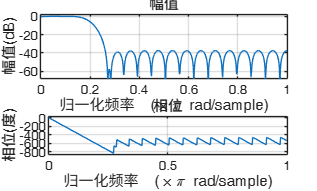


As = 10^(SNR/20);
Aj = 10^(JNR/20);
JNRa = 35;
Aja = 10^(JNRa/20);


    sp=randn([1,PRI_samp])+1j*randn([1,PRI_samp]);%噪声基底
    sp=sp/std(sp);
    white_noise = sp;
    sp1=sp;
    Bj = 20e6;
    fjc = 40e6;       % 瞄准的中心频率
    lpFilt = fir1(34, Bj/(fs),chebwin(35,30)); 
    freqz(lpFilt,1)

    sp1 = JNRa*filter(lpFilt, 1, sp1);
    % tj = (0:PRI_samp-1)/fs;
    % sp1 = sp1 .* exp(1j*2*pi*fjc*tj);  % 频移

jam = zeros(data_num,N_total);

k = 5;%+randi([3, 6]);  % 随机产生3-6个假目标
inte_time = 2e-6;
time = (k-1)*inte_time + taup;
lfm_d = zeros(1,round(time*fs));
lfm_dt = zeros(1,round(3*time*fs));
for i =1:3*k
    left = (i-1)*inte_time*fs + 1;
    right = left + Ntau -1;
    lfm_dt(left:right) = lfm_dt(left:right) + lfm;
end


lfm_d(1:round(time*fs)) = lfm_dt(Ntau+1:Ntau+round(time*fs))

lfm_d =   -5.0000 - 0.0000i  -4.9118 + 0.3075i  -4.6535 + 0.5819i  -4.2433 + 0.7970i  -3.7089 + 0.9324i  -3.0854 + 0.9758i  -2.4127 + 0.9238i  -1.7315 + 0.7825i  -1.0808 + 0.5662i  -0.4946 + 0.2965i  -0.0000 + 0.0000i   0.3850 - 0.2946i   0.6519 - 0.5589i   0.8016 - 0.7676i   0.8438 - 0.9008i   0.7954 - 0.9462i   0.6780 - 0.8995i   0.5163 - 0.7654i   0.3349 - 0.5566i   0.1565 - 0.2932i  -0.0000 + 0.0000i  -0.1213 + 0.2951i  -0.1999 + 0.5640i  -0.2346 + 0.7810i  -0.2300 + 0.9248i  -0.1951 + 0.9808i  -0.1420 + 0.9423i  -0.0841 + 0.8111i  -0.0346 + 0.5974i  -0.0041 + 0.3190i   0.0000 - 0.0000i  -0.0249 - 0.3314i  -0.0766 - 0.6451i  -0.1476 - 0.9113i  -0.2263 - 1.1034i  -0.2980 - 1.1996i  -0.3459 - 1.1849i  -0.3532 - 1.0521i  -0.3050 - 0.8026i  -0.1896 - 0.4462i  -0.0000 + 0.0000i   0.2649 + 0.5123i   0.5998 + 1.0625i   0.9933 + 1.6198i   1.4279 + 2.1531i   1.8815 + 2.6329i   2.3287 + 3.0335i   2.7427 + 3.3345i   3.0970 + 3.5218i   3.3678 + 3.5886i


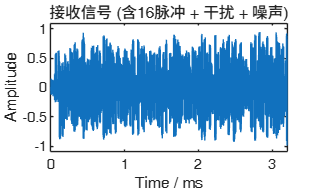

Ndelay = length(lfm_d);
jam_mat = [lfm_d ,zeros(1,2*Ndelay);zeros(1,Ndelay),lfm_d,zeros(1,Ndelay);zeros(1,2*Ndelay),lfm_d];
for m = 1:data_num
    % 生成高斯白噪声
    sp = randn([1,N_total]) + 1j*randn([1,N_total]);
    sp = sp / std(sp);
    white_noise = sp;

    % ======================================================================
    % === 生成密集假目标干扰 (Dense False Target Jamming - DFTJ) ===
    % ======================================================================

    % --- 1. 创建一个PRI长度的干扰信号模板 ---
    % 我们首先在一个PRI内生成假目标，,然后把剩余的PRI里塞满假目标
    jam_signal = zeros(1, N_total+PRI_samp);

    % --- 2. 循环生成每个假目标并放入模板 ---

    % 延迟时间为脉宽*干扰机个数 (10us*data_num)，
    delay_samp = 3*Ndelay;

    % 第一个假目标相对于真实目标的位置
    left_range = target_start_idx_in_PRI + Ndelay*(m-1) + Ntau +1;
    right_range = left_range + length(jam_mat(m,:));
    % 生成0到2π之间的随机初始相位
    phi = 2 * pi * rand;  % 随机相位值
    % 给lfm信号添加随机初始相位（通用方法）
    lfm_with_phase = jam_mat(m,:) * exp(1j * phi);
    r = -3 + 6 * rand;
    Aj = 10^((JNR+ r)/20);
    jam_signal(left_range:right_range-1) = jam_signal(left_range:right_range-1) + Aj * lfm_with_phase;
    % 后续假目标相对于前一个假目标的位置

    while right_range <=N_total
        left_range = left_range + delay_samp ;
        right_range = left_range + length(jam_mat(m,:));
        % if mod(left_range -target_start_idx_in_PRI,PRI_samp) ~= 0
        % jam_signal(left_range:right_range) = jam_signal(left_range:right_range) + Aj * jam_mat(m,:);
        % end
        phi = 2 * pi * rand;  % 随机相位值
        % 给lfm信号添加随机初始相位（通用方法）
        lfm_with_phase = jam_mat(m,:) * exp(1j * phi);
        r = -3 + 6 * rand;
        Aj = 10^((JNR+ r)/20);
        jam_signal(left_range:right_range-1) = jam_signal(left_range:right_range-1) + Aj * lfm_with_phase;
    end

    % --- 3. 保存生成的干扰样本 ---
    jam(m, 1:N_total) = jam_signal(1:N_total)+sp;

end

% --- 加入目标与干扰 ---
range_tar = 1 + round(rand(1)*4000);
pure_echo = As*tx;
rx = As*tx + sum(jam) + sp;
rx = rx / max(abs(rx));

figure;
plot(t_total*1e3, real(rx));
axis([0 3.2 -1.1 1.1])
xlabel('Time / ms'); ylabel('Amplitude');
title('接收信号 (含16脉冲 + 干扰 + 噪声)');

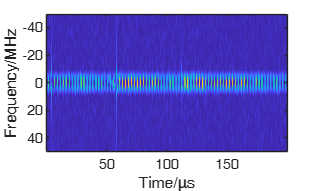



figure;
[S,F,T] = spectrogram(rx(PRI_samp+1:2*PRI_samp),32,32-8,200,fs, 'centered');
imagesc(T*1e6,F/1e6,abs(S));
% axis([0 100 -20 20])
ylabel('Frequency/MHz'); xlabel('Time/μs');


% === 匹配滤波（脉冲压缩） ===
h = conj(flip(lfm));
y = conv(rx, h);
env = abs(y);

% === 脉冲积累（非相干示例） ===
env_mat = reshape(env(1:Np*PRI_samp), PRI_samp, Np); % 每列一个脉冲
env_sum = abs(sum(env_mat, 2));  % 直接复数相加再取幅度
nenv_mat = reshape(y(1:Np*PRI_samp), PRI_samp, Np); % 每列一个脉冲
nenv_sum = sum(nenv_mat, 2); % 非相干积累

% 距离轴
c = 3e8;
rng_axis = (0:PRI_samp-1)*c/(2*fs);



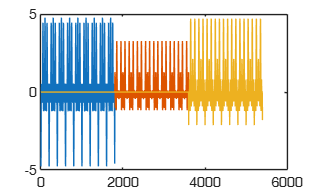


figure;
for i = 1:3
    phi = 2 * pi * rand;  % 随机相位值
    % 给lfm信号添加随机初始相位（通用方法）
    lfm_with_phase = jam_mat(i,:) * exp(1j * phi);
    plot(1:length(jam_mat(i,:)),lfm_with_phase)
    hold on
end

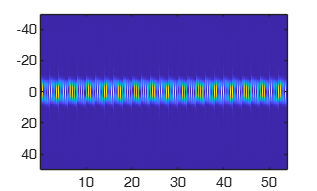


figure;
[S,F,T] = spectrogram(sum(jam_mat),32,32-8,200,fs, 'centered');
imagesc(T*1e6,F/1e6,abs(S));